clear;clc;close all

Load Train and Test datasets

load population_accidents

Create linear regression object poly1 refers to a first order polynomial

%[f,S,mu]=fit(x_train,y_train,'poly1')
f=fit(x_train,y_train,'poly1')

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0001324  (0.0001104, 0.0001545)
       p2 =       104.3  (-49.86, 258.5)

Predict the Output

y_predicted_train=feval(f,x_train);
y_predicted_test=feval(f,x_test);

Plot the data.

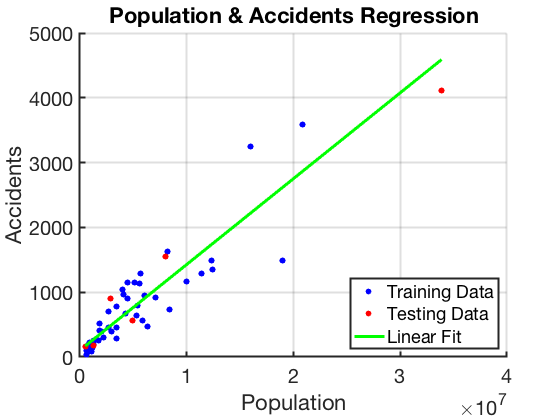

scatter(x_train,y_train,40,'ob','filled')
hold on
scatter(x_test,y_test,40,'or','filled')
plot(x_test,y_predicted_test,'g','LineWidth',3)
hold off
grid on

legend_text={'Training Data','Testing Data','Linear Fit'};
legend(legend_text,'Location','southeast');
xlabel('Population','fontsize',25);
ylabel('Accidents','fontsize',25);
title('Population & Accidents Regression','fontsize',25);
set(gca,'FontSize',20)
set(gca,'LineWidth',2);   

% save plot to a png file
print('linearregression-m.png','-dpng')

calculate the mean square error (MSE) of the test and training points

mse_train=sum((y_predicted_train-y_train).^2)/length(y_train)

mse_train = 1.1744e+05

mse_test=sum((y_predicted_test-y_test).^2)/length(y_test)

mse_test = 9.8539e+04

calculate the correlation coefficients for the training and test data sets with the associated linear fits hint: check out the function corrcoef

R_train = corrcoef(y_predicted_train,y_train)

R_train =     1.0000    0.8797
    0.8797    1.0000

R_test = corrcoef(y_predicted_test,y_test)

R_test =     1.0000    0.9830
    0.9830    1.0000

r_train=R_train(1,2)

r_train = 0.8797

r_test=R_test(1,2)

r_test = 0.9830

Draw a scatter diagram to characterize how good the linear estimates of the number of accidents are. This scatter diagram should include: 1. The 1:1 perfect fit line 2. The training data and its associated linear fit 3. The test data and its associated linear fit 4. A legend that contains the R value in the label

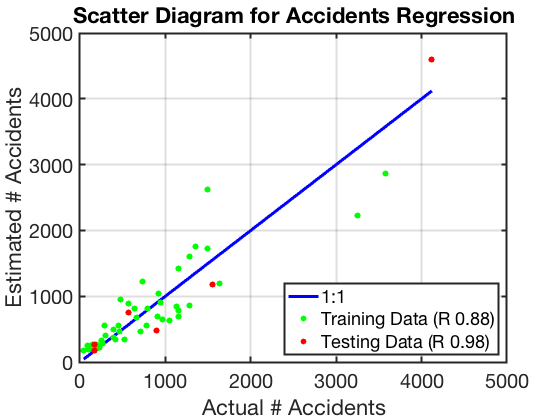

figure
plot([y_train' y_test'],[y_train' y_test'],'b','LineWidth',3)
hold on
scatter(y_train,y_predicted_train,40,'og','filled')
scatter(y_test,y_predicted_test,40,'or','filled')
hold off
grid on

legend_text={...
    ['1:1'],...
    ['Training Data (R ' num2str(r_train,2) ')'],...
    ['Testing Data (R ' num2str(r_test,2) ')']...
    };
legend(legend_text,'Location','southeast');
xlabel('Actual # Accidents','fontsize',25);
ylabel('Estimated # Accidents','fontsize',25);
title('Scatter Diagram for Accidents Regression','fontsize',25);
set(gca,'FontSize',20)
set(gca,'LineWidth',2);  
print('linearregression-scatter-m.png','-dpng')